## BECS4 Optimization Methods Final Project

#### Introduction

The detection and classification of handwritten digits is a very common task for the introduction to neural networks. For this project we use a prewritten neural network workflow from [Rodrigo Sánchez Molina](https://github.com/rsanchezm98) which is based on the coursery course on deep learning. 

The mnist data on handwritten digits is already preprocessed and ready to use.

Github:[https://github.com/rsanchezm98/neural-network-from-scratch.git](https://github.com/rsanchezm98/neural-network-from-scratch.git)

Originaly there are **60'000** digits to train the model. To increase the difficulty and have a better comparability between methods, only **20'000** digits were used. 

**Explanation for the usage of genetic algorithms in neural networks**

https://towardsdatascience.com/gas-and-nns-6a41f1e8146d

### NN-Architecture

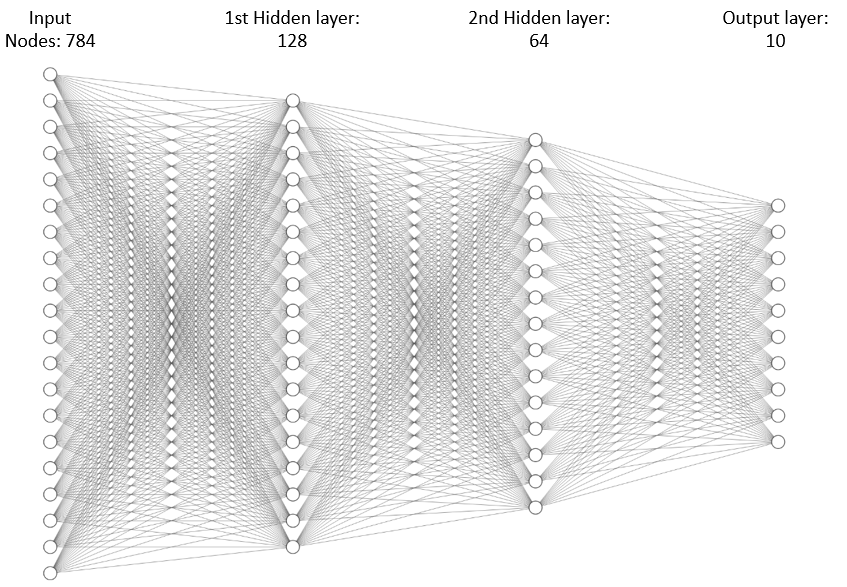

#### Input digits (28X28)

#### Project goal:

The first goal of the project is to evaluate different optimization methods to imporve the backpropagation of the model. The methods used are:

- Gradient descent 

- Mini-batch gradient descent 

- Stochastic gradient descent -X

- Adagrad. -X

- Adadelta. -> Eric

- RMSprop.

- Adam. -X

The second goal is to implement a genetic algorithm which finds the best initial weights for the first hidden layer to increase the accuracy. 

The following steps were implemented:

- Train 10 individual models over 3 epochs with random weights. 

#### Data visualization

rng(0); % seed for the random number generator
cd '/home/cewinharhar/GITHUB/becs4/neural_network_mninst'
disp('Loading data...')

Loading data...



% load train data
train_data = load('mnist_train.csv');

labels = train_data(:,1);
y = zeros(10,length(train_data)); % output labels for training
for i = 1:length(train_data)
    y(labels(i)+1,i) = 1;
end

% preprocessing
images = train_data(:,2:785);
images = images/255;
images = images'; % Input vectors for training

% load test data
test_data = load('mnist_test.csv');
test_labels = test_data(:,1);
test_y = zeros(10,10000);
for i = 1:length(test_data)
    test_y(test_labels(i)+1,i) = 1;
end

% preproessing
test_images = test_data(:,2:785);
test_images = test_images/255;
test_images = test_images';


size_hl1 = 100; % Number of neurons in the first hidden layer
size_hl2 = 50; % Number of neurons in the second hidden layer


% Construct model with specifed optimizer for training
lr = 0.001; % learning rate
model = NN(size_hl1, size_hl2, 'Adam', lr);

% Alternatively with SGD optimizer
% lr = 0.1;
% model = NN(hn1, hn2, 'SGD', lr);

epochs = 10; % Number of training epochs

batch_size = 100; % Mini-batch size

disp('Starting epoch 1');

Starting epoch 1


disp(' ');


% Epoch loop
for e = 1:epochs 
    
    samples = 1;
    
    % Loop over gradient descent steps
    for j = 1:length(train_data)/batch_size 
        
        for i = samples:samples+batch_size-1 % Loop over each minibatch

            % Calculate gradients with backpropagation
            model = model.backpropagate(images(:,i), y(:,i));
            
        end
    
        % Gradient descent (optimizer step)
        model = model.step();
          
        % Number of data points covered (+1)
        samples = samples + batch_size;
    
    end
    
    fprintf('Epochs:');
    disp(e) % Track number of epochs
    
    
    % Evaluate model accuracy
    disp('Evaluating model')
    hits = 0;
    n = length(test_data);
    for i = 1:n

        out = model.predict(test_images(:,i)); % model prediction vector
        [~, num] = max(out); % Find highest prediction score

        if test_labels(i) == (num-1)
            hits = hits + 1; % Count the number of correct classifications
        end

    end
    fprintf('Accuracy: ');
    fprintf('%f',hits/n*100);
    disp(' %');
    disp(' ');
    
    
    [images,y] = shuffle(images,y); % Shuffle order of the images for next epoch
end

Epochs:

     1



Evaluating model


Accuracy: 

93.150000

 %


Epochs:

     2



Evaluating model


Accuracy: 

95.380000

 %


Epochs:

     3



Evaluating model


Accuracy: 

96.260000

 %


Epochs:

     4



Evaluating model


Accuracy: 

96.790000

 %


Epochs:

     5



Evaluating model


Accuracy: 

97.090000

 %


Epochs:

     6



Evaluating model


Accuracy: 

97.540000

 %


Epochs:

     7



Evaluating model


Accuracy: 

97.580000

 %


Epochs:

     8



Evaluating model


Accuracy: 

97.600000

 %


Epochs:

     9



Evaluating model


Accuracy: 

97.670000

 %


Epochs:

    10



Evaluating model


Accuracy: 

98.020000

 %



disp('Done');

Done
